close all
clear all

## Motor izquierdo

% Función de transferencia de velocidad del motor
G1 = tf(5060,[1  162.6]);

%Parámetros de diseño
Tes = 1;
Mp = 0.05; 
% Polos y ceros
sigma = 4/Tes;
wd = -pi*sigma/log(Mp);
s1 = -sigma+wd*1j

s1 = -4.0000 + 4.1948i

s2 = -sigma-wd*1j

s2 = -4.0000 - 4.1948i


so = -4*sigma

so = -16

% Controlador
Ti = -1/so

Ti = 0.0625

Gc_p = tf([1 1/Ti], [1 0])


Gc_p =
 
  s + 16
  ------
    s
 
Continuous-time transfer function.
Model Properties


Gol = Gc_p*G1


Gol =
 
  5060 s + 80960
  --------------
  s^2 + 162.6 s
 
Continuous-time transfer function.
Model Properties


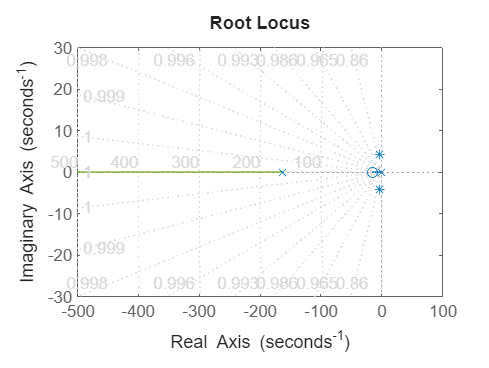

figure(1)
rlocus(Gol)
grid on
hold on 
plot([-sigma  -sigma],[wd  -wd],'*')
% axis([-8 5 -3  3])
hold off

Kp1= 0.014%0.109;

Kp1 = 0.0140

%En lazo cerrado
Glc = feedback(Kp1*Gol,1)


Glc =
 
     64.65 s + 1034
  --------------------
  s^2 + 215.9 s + 1034
 
Continuous-time transfer function.
Model Properties


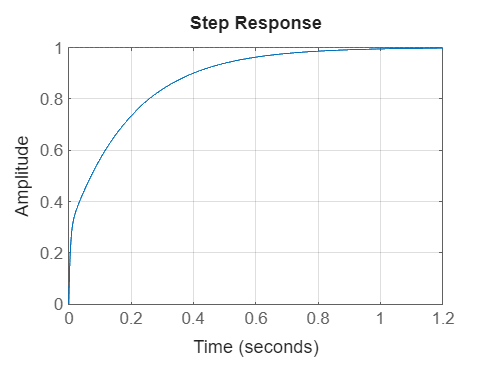


figure(2)
step(Glc);
% axis([0 1 0 1])
grid on

% Tiempo de subida
Tr = 0.117

Tr = 0.1170

T = 0.001

T = 1.0000e-03

## Motor derecho

G2 = tf(4618,[1  151.2]);
% Controlador
Ti = -1/so

Ti = 0.0625

Gc_p = tf([1 1/Ti], [1 0])


Gc_p =
 
  s + 16
  ------
    s
 
Continuous-time transfer function.
Model Properties


Gol = Gc_p*G2


Gol =
 
  4618 s + 73888
  --------------
  s^2 + 151.2 s
 
Continuous-time transfer function.
Model Properties


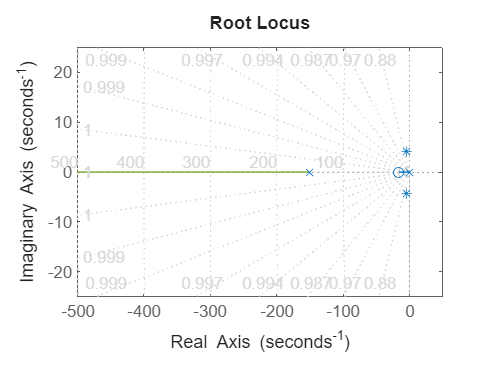

figure(1)
rlocus(Gol)
grid on
hold on 
plot([-sigma  -sigma],[wd  -wd],'*')
% axis([-8 5 -3  3])
hold off

Kp2= 0.0142 %0.111;

Kp2 = 0.0142

%En lazo cerrado
Glc = feedback(Kp2*Gol,1)


Glc =
 
     65.58 s + 1049
  --------------------
  s^2 + 216.8 s + 1049
 
Continuous-time transfer function.
Model Properties


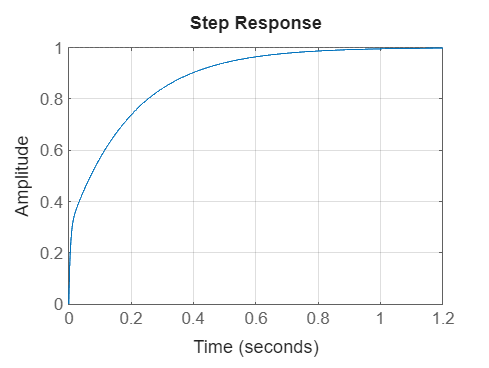


figure(2)
step(Glc);
% axis([0 1 0 1])
grid on